# 垂直跳び　床反力分析

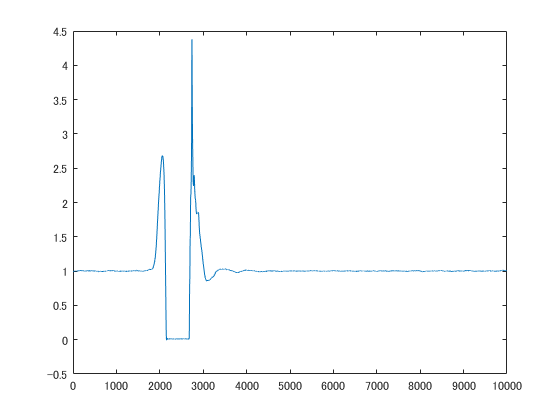

clear
close all
clc


% load 
fileName = 'DemoDataSJ' ;
load(fileName) ;

%
fz = grfs(:,3) + grfs(:,6) ;
plot(fz)



%
alpha = 3 ; % [ % weight]
tOnsetSJ = detect_SJ_onset(fz, alpha)

tOnsetSJ = 1827

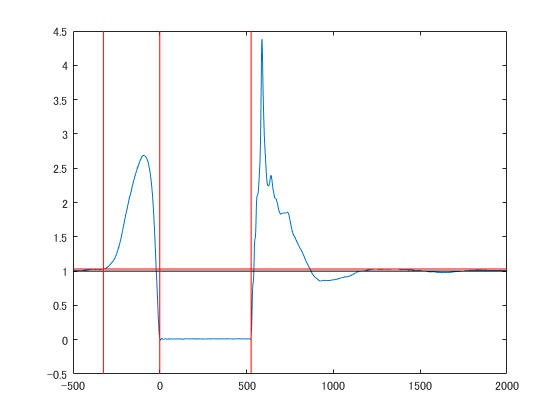



% takeoff
beta = 3 ;
win = 30 ;
n = length(fz) ;
for ii = tOnsetSJ:n-win
    if all( fz(ii:ii+win) < 0.01*beta )
        tTakeOff = ii ;
        break
    end
end

% landing
for ii = tTakeOff:n-win
    if all( fz(ii:ii+win) > 0.01*beta )
        tLanding = ii ;
        break
    end
end


% power
y2dot = (fz - 1) * gravity ;  % [m/s2]
ydot = cumtrapz(y2dot) * 0.001 ; % [m/s]
y = cumtrapz(ydot) * 0.001 ; % [m]
y = y - y(tOnsetSJ) ;

grfPower = fz.*ydot ; % [N/weight * m/s] = [J/s /weight] = [W/weight]
peakPower = max(grfPower) * gravity ; % [W / kg] ### weight = m [kg] * g [m/s2]

%
tData = [1:n] - tTakeOff ;

figure
plot(tData, fz)
lineplot(1, 'h', 'k') ;
lineplot(1+0.01*alpha, 'h', 'r') ;
lineplot(tData([tOnsetSJ, tTakeOff, tLanding]), 'v', 'r') ;

set(gca, 'xlim', [-500,2000])

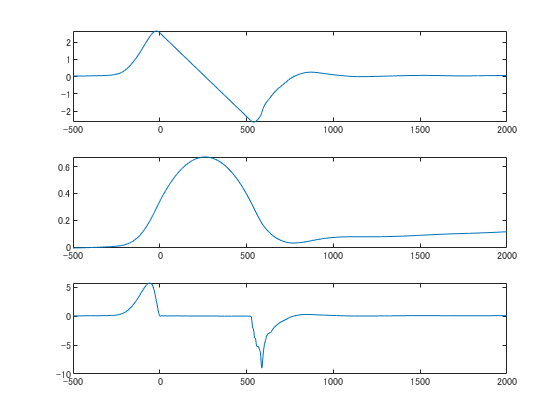


figure
subplot(3,1,1) ;
plot(tData, ydot)
set(gca, 'xlim', [-500,2000])

subplot(3,1,2) ;
plot(tData, y)
set(gca, 'xlim', [-500,2000])

subplot(3,1,3) ;
plot(tData, grfPower)
set(gca, 'xlim', [-500,2000])

function D = load_sample_data()

    clear
    close all
    clc
    
    iSubject = 99 ;
    dataFilePath = sprintf('../data matfiles 1/Data_S%02d', iSubject) ;
    load(dataFilePath) ;
    
    D = DataStruct.SJ(1) ;

end


function onset = detect_SJ_onset(fz, alpha)

    baseWindow = 1000 ;
    baseFz = mean(fz(1:baseWindow)) ;
    
    win = 30 ;
    n = length(fz) ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) > baseFz+0.01*alpha )
            onset = ii ;
            break
        end
    end
    
end

